# Positive Real Passivity Enforcement

## Introduction

Positive real passivity enforcement is a passivity enforcement method based on the Kalman-Yakubovic-Popov (KYP) inequality or Positive-Real Lemma [1]. This states, that if there exists a solution $X=X^\mathrm{T}>0$ that solves the KYP LMI 

$Z(X) = \pmatrix{A^\mathrm{T}X + XA & XB-C^\mathrm{T} \cr B^\mathrm{T}X-C & -(D+D^\mathrm{T})} \le 0$,

the system is passive. If the system under concern is not passive we can perturb the output matrix $C$ resulting in a modified KYP LMI

$\hat{Z}(X,\Xi) = \pmatrix{A^\mathrm{T}X + XA & XB-C^\mathrm{T}-R^{-1}\Xi^\mathrm{T} \cr B^\mathrm{T}X-C-\Xi R^{-\mathrm{T}} & -(D+D^\mathrm{T})} \le 0$.

Here, a coordinate transformation was applied to the perturbation by means of the Cholesky factor of the controllability Gramian $R$, that allows to look for a $\mathcal{H}_2$-optimal perturbation. Then, passivity enforcement results in solving the constrained optimization problem

$\min_{X,\Xi} ||\Xi||_F^2 \quad \text{s.t.} \quad X=X^\mathrm{T} >0 \; \text{and} \; \hat{Z}(X,\Xi) \le 0 $,

that looks for the smallest perturbation $\Xi$ that renders the system passive. 

### Pseudo-Code

## Toolbox Implementation

The MORpH toolbox provides an implementation of positive real passivity enforcement in the function prl*PasEnf*.

For more information, refer to the documentation:

help prlPasEnf

  prlPasEnf - Enforce passivity of LTI system by passivity enforcement via
              Positive Real Lemma.
 
  Syntax:
    sysp = prlPasEnf(sys)
    sysp = prlPasEnf(sys, opts)
 
  Description:
        sysp = prlPasEnf(sys, opts) perturbs matrix C of sys to obtain a
        passive model sysp by searching for the solution of the modified
        KYP inequality.
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:      sss object, containing LTI system
        *Optional Input Arguments:*
        - Opts:  structure with execution parameters
            - .tol:            Tolerance for solution X to KYP inequality to be
                                positive definite.
                                [{1e-8} / positive double]
            - .verbosity:       Regulates ouput of cvx in command window.
                                [{0} / 1]
            - .solver:          Define the solver for the P

## Example

The example considered here is a SISO Ladder Network with an architecture as shown below:  

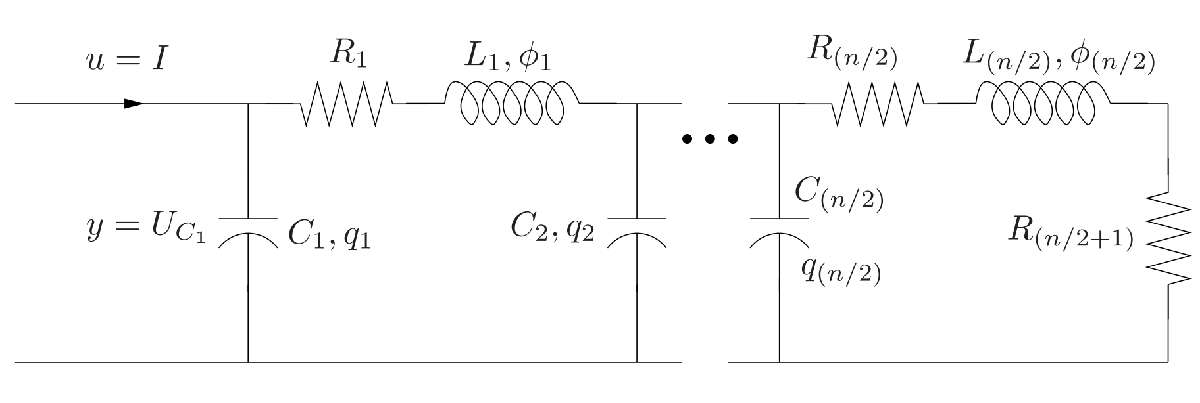

Image source: [2]

We consider a model with dimension $n = 100$, i.e. 50 inductances ($L_i = 0.2\text{H}$), 50 capacitors ($C_i = 0.2\text{F}$) and 51 resistances ($R_i=1\Omega$).

sys = sss(setup_LadderNetworkSystem(100,.2,.2,1))

sys =   (SSS)(SISO)
  100 state variables, 1 inputs, 1 outputs
  Continuous-time state-space model.


We reduce the 

sysr = irka(sys,10,struct('stopCrit','s0','maxiter',200,'tol',1e-5))

IRKA step 024 - Convergence (s0):  7.4e-06 

sysr =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8         x9        x10
   x1   -0.007913   -0.01923   -0.02042   -0.01829   -0.01677   -0.01837   -0.01305   0.003374   0.006377   0.001224
   x2    -0.01923    -0.1307    -0.1845     -0.164    -0.1477    -0.1599    -0.1132    0.02827    0.05229   0.007982
   x3    -0.02042    -0.1845    -0.4929    -0.5497    -0.4592    -0.4668    -0.3269     0.0698     0.1137  -0.007335
   x4    -0.01829     -0.164    -0.5497     -1.068     -1.021    -0.7652    -0.4986    0.04376   -0.06328    -0.1843
   x5    -0.01677    -0.1477    -0.4592     -1.021     -1.503    -0.6936     0.1163    -0.2264     -1.252    -0.7925
   x6    -0.01837    -0.1599    -0.4668    -0.7652    -0.6936     0.6258      2.546     -1.474     -3.815     -1.667
   x7    -0.01305    -0.1132    -0.3269    -0.4986     0.1163      2.546      4.625     -2.768     -3.995   -0.06642
   

isPassive(ss(sysr))

ans = logical
   0


*prlPasEnf* in its simplest form is called by providing the non-passive system: 

warning('off','all')
sysp = prlPasEnf(sysr)

sysp =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8         x9        x10
   x1   -0.007907   -0.01869    -0.0157   0.001062    0.03293    0.05529    0.04324   -0.02591   -0.04069    0.01246
   x2    -0.01927    -0.1284    -0.1551   -0.02075      0.256     0.4706     0.3604    -0.2071    -0.3268     0.1113
   x3    -0.02055    -0.1823    -0.4455    -0.2397     0.5928      1.377      1.041    -0.5284     -0.901     0.2728
   x4    -0.01836    -0.1629    -0.5173    -0.7644     0.4256      2.516      2.075    -0.7154     -1.805      -0.25
   x5    -0.01627    -0.1444    -0.4586     -1.004    -0.8864      2.469      3.692    -0.4678     -3.268     -3.357
   x6    -0.01797    -0.1595    -0.5064     -1.109     -2.123     -1.246       3.72     -1.856     -1.934     -2.437
   x7    -0.01447    -0.1284    -0.4077    -0.8925      -1.71     -3.861     -2.674     -2.947       1.43      10.02
   x8     0.00242    0.02148    0.06821     0.14

norm(ss(sys) - ss(sysp))

ans = 5.8451e-04

isPassive(ss(sysp))

ans = logical
   1


### Options

prl*PasEnf* levels of options are:

- Top level (prl*PasEnf*): e.g. LMI solver

- Second level (ss2phs): e.g. pH representation

- Third level (*phs*): e.g. switching on/off input validation

You can find more information on the respective options by having a look at the documentation, e.g.

help ss2phs

  ss2phs - Returns pH system representation of a given passive system
 
  Syntax:
    sysPH = ss2phs(sys)
    sysPH = ss2phs(sys,X)
    sysPH = ss2phs(sys,Opts)
    sysPH = ss2phs(sys,X,Opts)
 
  Description:
        This funciton uses the Kalman-Yakubovic-Popov Lemma to construct a
        port-Hamiltonian system representation of a given passive
        ss object.
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:  ss object to be brought in pH representation
        *Optional Input Arguments:*
        - X: solution to positive real Riccati equation
        - Opts: structure with execution parameters
            - .tol:             If D+D' is not positive definite, D is replaced
                                by Opts.tol*eye(m).
                                [{1e-12} / positive double]
            - .representation:  Defines the pH system representation
                       

To provide these options, use nested structs. As example, the following code changes the reduced system to be port-Hamiltonian:

Opts = struct();
Opts.makePH = true;     % Return pH system
Opts.ss2phs.method = @prlPasEnf; % Reduction method for info
Opts

Opts = struct with fields:
    makePH: 1
    ss2phs: [1×1 struct]


sysp = prlPasEnf(sysr,Opts)

sysp =   phsRed with properties:

      parameters: [1×1 struct]
          method: @prlPasEnf
            info: []
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 1
           isDAE: 0
    hasStaircase: 1


norm(ss(sys) - ss(sysp))

ans = 5.8452e-04

### Output

*prlPasEnf* provides only the passive system as output. This ssRed/phsRed object contains additional information which makes the creation more transparent:

sysp.method    % Method with which the system was created (should be @prlPasEnf)

ans = function_handle with value:
    @prlPasEnf


sysp.parameters     % Execution parameters (options)         

ans = struct with fields:
       makePH: 1
       ss2phs: [1×1 struct]
    verbosity: 0
          tol: 1.0000e-08
       solver: 'cvx'
       yalmip: [1×1 struct]
            X: [10×10 double]


## References

[1] Grivet-Talocia, Gustavsen, "Passive Macromodeling Theory and Applications", 2016.

[2] R. V. Polyuga, "Model reduction of port-Hamiltonian systems", PhD thesis, University of Groningen, 2010.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Maximilian Bonauer    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)